## Question 3

warning('off','all')
nuke;
warning('on','all')

### Setting up figure

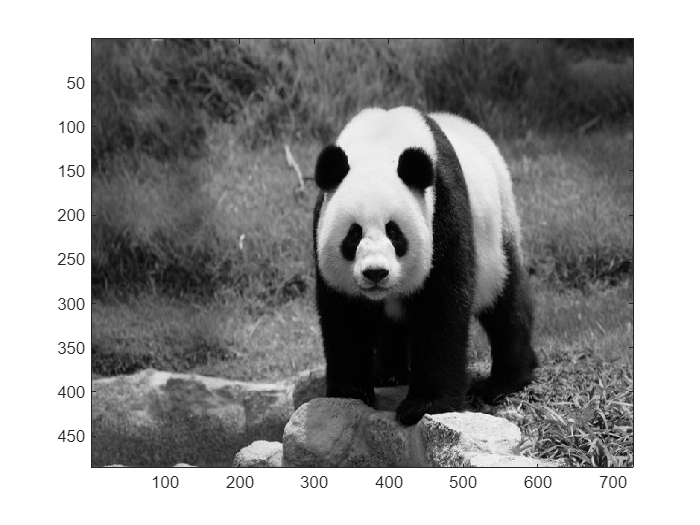

f = imread('file.jpg');
f = im2gray(f);          
f = double(f); 
image(f); colormap gray; 


[rows, cols,numberOfColorChannels] = size(f);

X_range = [-cols/2, cols/2];
Y_range = [-rows/2, rows/2];

% Create a grid for the X and Y values
x = linspace(X_range(1), X_range(2), cols);
y = linspace(Y_range(1), Y_range(2), rows);

### Setting up gaussian

disp('Setting up gaussian');

Setting up gaussian


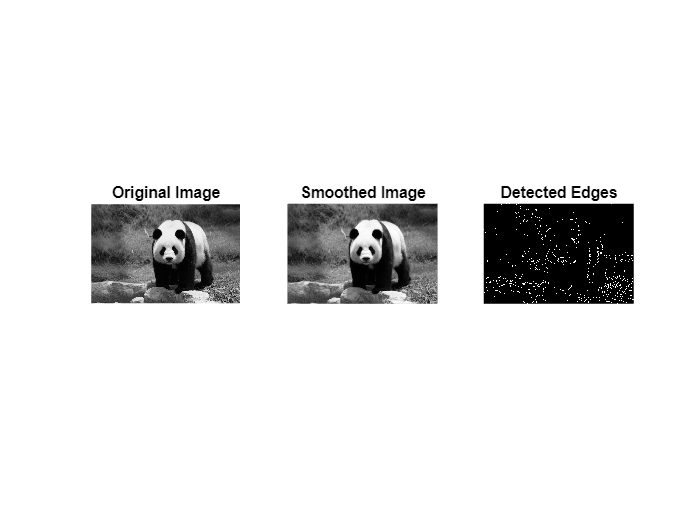

sigma = 1;  

g = @(x) (1 / (sqrt(2 * pi) * sigma)) * exp(-x.^2 / (2 * sigma^2));
G = @(x, y) g(x) .* g(y); % 2D Gaussian function

% Create Gaussian kernel in 2D space (size determined by the image)
half_filter_size = 3 * sigma; % Typically 3*sigma is a good filter size
x_filter = linspace(-half_filter_size, half_filter_size, round(6 * sigma + 1));
y_filter = linspace(-half_filter_size, half_filter_size, round(6 * sigma + 1));

% Create the 2D Gaussian kernel G(x, y)
[X, Y] = meshgrid(x_filter, y_filter);
gaussian_kernel = G(X, Y);

% Normalize the kernel to ensure the sum of the weights is 1
gaussian_kernel = gaussian_kernel / sum(gaussian_kernel(:));

% Perform convolution (with 'same' option to keep the output size same as input)
fsmooth = conv2(f, gaussian_kernel, 'same');

% Compute the gradient of the smoothed image (first derivatives)
[Gx, Gy] = gradient(fsmooth);

% Compute the gradient magnitude
grad_mag = sqrt(Gx.^2 + Gy.^2);

% Compute the second-order derivative (Laplacian)
% Using a Mexican hat kernel for the second-order derivative
M = @(x, y, sigma) (x.^2 + y.^2 - 2*sigma^2) .* exp(-(x.^2 + y.^2) / (2 * sigma^2)) / (sqrt(2 * pi) * sigma^4); 
mexican_hat_kernel = M(X, Y, sigma);

% Convolve the image with the Mexican hat kernel to get the Laplacian
laplacian = conv2(fsmooth, mexican_hat_kernel, 'same');

% Define thresholds for edge detection
d1 = 10; % Threshold for gradient magnitude
d2 = 7;  % Threshold for Laplacian (second-order derivative)

% Detect edges based on the conditions
edges = (grad_mag > d1) & (abs(laplacian) < d2);

% Display the results
figure;
subplot(1, 3, 1), imshow(f, []), title('Original Image');
subplot(1, 3, 2), imshow(fsmooth, []), title('Smoothed Image');
subplot(1, 3, 3), imshow(edges, []), title('Detected Edges');